# Lab 9 by Cole Bardin     Section 62

## Curve Fitting

## Part A

## Question 1

clc, clear, close all
filename = 'carbon_emissions_data.mat';
load(filename)

time = carbon_emissions_data(:,1); % Date/time in years. (column 1)
carbon = carbon_emissions_data(:,2); % carbon emissions data (column 2)

fig1 = figure();

plot(time, carbon, 'b', "LineWidth", 4)
title("Global Carbon Emissions in Million Metric Tons of Carbon")
ylabel("Carbon Emission")
xlabel("Year")

% Question 2
hold on
shift = mean(time); % exact mean of the data is 1883
D = [ones(size(time)) (time - shift)]; % we expand about the midyear of the data
b = inv(D'*D)*D'*carbon;
D2 = D' * D

D2 =          263           0
           0     1515932


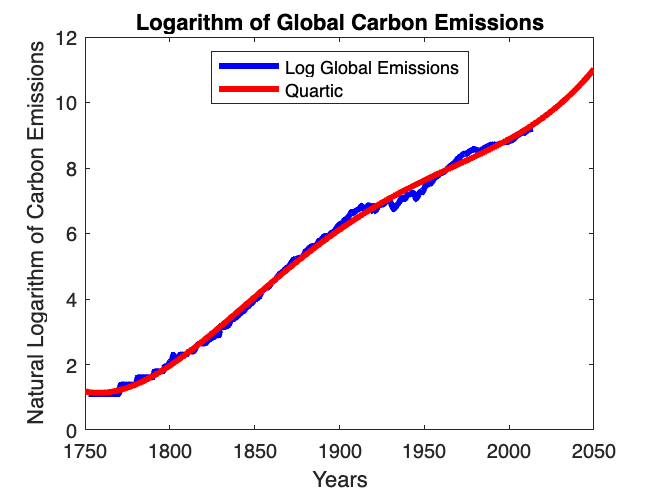


% Question 3-4
y1 = @ (t) b(1) + b(2) * (t - shift); % best-fit line

best_line = plot([1750, 2050], y1([1750, 2050]), 'r', 'LineWidth', 3);
legend(["Global Emissions", "Linear"], "Location", "North")

%% Question 5
clc, clear, close all
filename = 'carbon_emissions_data.mat';
load(filename)

time = carbon_emissions_data(:,1); % Date/time in years. (column 1)
carbon = carbon_emissions_data(:,2); % carbon emissions data (column 2)

figure()
L = log(carbon); % natural logarithm of global carbon emissions

plot(time, L, 'b', "LineWidth", 3);
title("Logarithm of Global Carbon Emissions")
ylabel("Natural Logarithm of Carbon Emissions")
xlabel("Years")

y = log(carbon);
shift = mean(time); % exact mean of the time data
% next, expand about the mean of the data
D = [ones(size(time)) (time - shift) (time - shift).^2]; 
b = inv(D' * D) * D' * y;

hold on
y2 = @ (t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2;
%best_line = plot(1750:1:2050, y2(1750:1:2050), 'r', 'LineWidth', 3);
%legend(["Log Global Emissions", "Quadratic"], "Location","North")

D = [ones(size(time)) (time - shift) (time - shift).^2 (time - shift).^3 (time - shift).^4]; 
D2 = sym(D'*D);
b = inv(D2) * D' * y;
y3 = @ (t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2 + b(4) * (t - shift).^3 + b(5) * (t - shift).^4;
best_line = plot(1750:1:2050, y3(1750:1:2050), 'r', 'LineWidth', 3);
legend(["Log Global Emissions", "Quartic"], "Location","North")

## Part B

## Questions 6-7

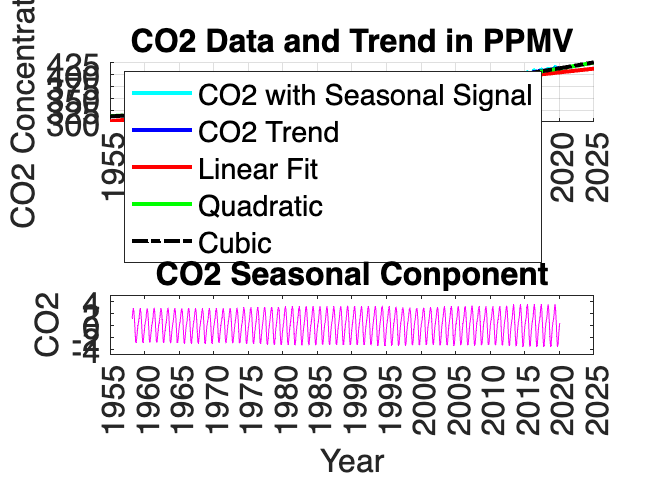

clear, clc, close all
filename = 'carbon_dioxide_data.mat'; % Data for the Keeling curve
load(filename);

time = carbon_dioxide_data(:,3); % Date/time in decimal years.
CO2 = carbon_dioxide_data(:,5); % CO2 data
CO2_trend = carbon_dioxide_data(:,6); % CO2 data trend

fig = figure(6);
subplot(2,1,1)
hold on
grid on
plot(time, CO2, 'cyan', "LineWidth",2)
plot(time, CO2_trend, 'b', "LineWidth",2)
title("CO2 Data and Trend in PPMV")
xlabel("Year")
ylabel("CO2 Concentration")
axis([1955, 2025, 300, 425])
yticks(300:25:425)
xticks(1955:5:2025)

subplot(2,1,2)
grid on
plot(time, CO2-CO2_trend, 'magenta')
title("CO2 Seasonal Conponent")
xlabel("Year")
ylabel("CO2")
axis([1955, 2025, -5, 5])
xticks(1955:5:2025)
yticks(-4:2:4)

fontsize(fig, 16, "points")

% Question 8
n = numel(time);
subplot(2,1,1) % add the best-line to the top tile.
shift = mean(time); % numerical mean of the time data
D = [ones(size(time)) (time - shift)]; % allows to shift time series to the mean
b = inv(D'*D)*D'*CO2_trend;

y4 = @(t) b(1) + b(2) * (t - shift);

subplot(2,1,1)
hold on
plot([1955,2025], y4([1955,2025]), 'r', "LineWidth",2)

% Question 9
tpts = 1955:1:2025;
D = [ones(size(time)) (time - shift) (time - shift).^2]; % allows to shift time series to the mean
b = inv(D'*D)*D'*CO2_trend;
y5 = @(t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2;
plot(tpts, y5(tpts), 'g', "LineWidth",2)

% Question 10
% design matrix for a cubic fit
D = [ones(size(time)) (time - shift) (time-shift).^2 (time-shift).^3];
b = inv(D'*D)*D'*CO2_trend;
y6 = @(t) b(1) + b(2) * (t - shift) + b(3) * (t - shift).^2 + b(4) * (t - shift).^3;
plot(tpts, y6(tpts), 'k-.', "LineWidth",2)

legend(["CO2 with Seasonal Signal","CO2 Trend", "Linear Fit", "Quadratic", "Cubic"], "Location","NorthWest")